%Fonctions de transfert et modèle d'état
P=[6 5 0 3 2 1 0];
%Pour obtenir les racines on met les polynomes dans un vecteur
%for k = 1:length(r)
%    fprintf('r%d = %.4f %+.4fi\n', k, real(r(k)), imag(r(k)));
%end
r=roots(P);
disp(r);

   0.0000 + 0.0000i
  -1.1067 + 0.0000i
   0.4481 + 0.6448i
   0.4481 - 0.6448i
  -0.3114 + 0.3837i
  -0.3114 - 0.3837i



%la pulsation naturelle et l'amortissement des pôles complexes conjugés :
damp(P);

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -1.11e+00                 1.00e+00       1.11e+00          9.04e-01    
  4.48e-01 + 6.45e-01i    -5.71e-01       7.85e-01         -2.23e+00    
  4.48e-01 - 6.45e-01i    -5.71e-01       7.85e-01         -2.23e+00    
 -3.11e-01 + 3.84e-01i     6.30e-01       4.94e-01          3.21e+00    
 -3.11e-01 - 3.84e-01i     6.30e-01       4.94e-01          3.21e+00    


%F=tf([1 1 0],[1 3 1 1]);%ou
s=tf('s');
F=(s^2+s)/(s^3+3*s^2+s+1);
pole(F)

ans =   -2.7693 + 0.0000i
  -0.1154 + 0.5897i
  -0.1154 - 0.5897i


zero(F)%zéros

ans =      0
    -1


dcgain(F)%gain statique : c'est la valeur de la sortie en régime permanent pour une entrée constante (typiquement un échelon de 1), si le régime permanent existe.

ans = 0

zpk(F)%factoriser la fonction de transfert


ans =
 
               s (s+1)
  ----------------------------------
  (s+2.769) (s^2 + 0.2307s + 0.3611)
 
Continuous-time zero/pole/gain model.


%On peut opérer différents calculs sur les fonctions de transfert (addition, multiplication, etc...).
%revanche, il faut être vigilant car Matlab ne procède pas aux simplifications. Comparez par
%En exemple :
F=tf([1],[1 1])


F =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.


G=F/1+F


G =
 
     2 s + 2
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.


H=minreal(F/1+F)


H =
 
    2
  -----
  s + 1
 
Continuous-time transfer function.


A=[0 1 0; 0 0 1; -1 -1 -3];
B=[0; 0; 1];
C=[0 1 1];
D=[0];
sys=ss(A,B,C,D);
% La fonction ss(A,B,C,D) permet de creer un modele en espace d'etat
% d'un systeme dynamique lineaire sous la forme :
% x_dot = A x + B u
% y     = C x + D u
%
% A represente la dynamique interne du systeme (evolution des etats)
% B indique comment l'entree influence les etats
% C relie les etats a la sortie
% D represente une transmission directe entree-sortie
%
% pole(sys) retourne les poles du systeme, c'est-a-dire les valeurs
% propres de la matrice A. Les poles determinent la stabilite :
% - partie reelle negative  -> systeme stable
% - partie reelle positive  -> systeme instable
%
% eig(sys) retourne les valeurs propres de la matrice A.
% Pour un systeme continu en espace d'etat :
% eig(sys) = pole(sys)
%
% damp(sys) calcule les caracteristiques dynamiques associees aux poles :
% - facteur d'amortissement (zeta)
% - pulsation naturelle (wn)
% Cela permet d'interpreter physiquement le comportement du systeme
% (sous-amorti, critique, sur-amorti) et sa rapidite de reponse.
sys.a

ans =      0     1     0
     0     0     1
    -1    -1    -3


% Interpretation :
% damp donne :
% - le facteur d'amortissement (zeta)
% - la pulsation naturelle (wn)
% - les poles
% zeta < 1  -> systeme sous-amorti (oscillations)
% zeta = 1  -> amortissement critique
% zeta > 1  -> sur-amorti
% wn donne la rapidite du systeme
damp(sys)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.15e-01 + 5.90e-01i     1.92e-01       6.01e-01         8.67e+00    
 -1.15e-01 - 5.90e-01i     1.92e-01       6.01e-01         8.67e+00    
 -2.77e+00                 1.00e+00       2.77e+00         3.61e-01    



eig(sys)

ans =   -2.7693 + 0.0000i
  -0.1154 + 0.5897i
  -0.1154 - 0.5897i


pole(sys)

ans =   -2.7693 + 0.0000i
  -0.1154 + 0.5897i
  -0.1154 - 0.5897i


% On peut convertir un modele en espace d'etat (ss) en fonction de transfert
% avec tf(sys) ou en representation zero-pole-gain avec zpk(sys).
%
% tf(sys) donne la forme numerateur / denominateur classique G(s).
% zpk(sys) donne directement les zeros, poles et le gain du systeme.
%
% En SISO on obtient une seule fonction de transfert.
% En MIMO on obtient une matrice de fonctions de transfert.

tf(sys)


ans =
 
        s^2 + s
  -------------------
  s^3 + 3 s^2 + s + 1
 
Continuous-time transfer function.


zpk(sys)


ans =
 
               s (s+1)
  ----------------------------------
  (s+2.769) (s^2 + 0.2307s + 0.3611)
 
Continuous-time zero/pole/gain model.


s=tf('s');
F=1/(s^3+3*s^2+s+1)


F =
 
           1
  -------------------
  s^3 + 3 s^2 + s + 1
 
Continuous-time transfer function.


stepinfo(F)

ans = struct with fields:
         RiseTime: 2.0890
    TransientTime: 33.3817
     SettlingTime: 33.3817
      SettlingMin: 0.7156
      SettlingMax: 1.5268
        Overshoot: 52.6780
       Undershoot: 0
             Peak: 1.5268
         PeakTime: 5.5891


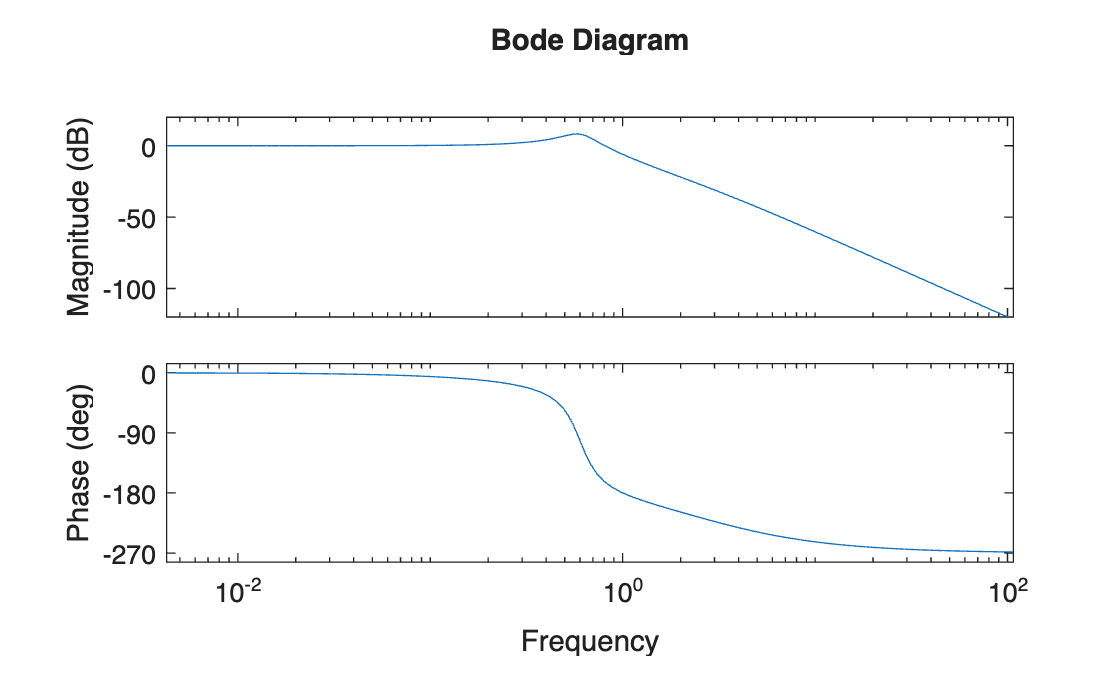

%tracer le graphe de bode
bode(F)